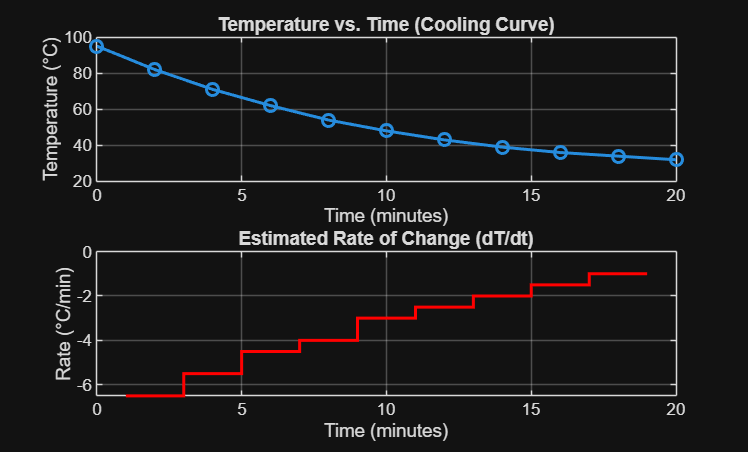

%{
Cooling Curve Approximation (Data + Area)
Author: Diem-Linh Phan
Date: 4-30-2026
Purpose:
    Models a cooling curve
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showing the cooling curve and rate of change 
MATLAB tools/functions:
    - functions
    - plots
    - tables
%}
% 1. 0 to 20 minutes with a step of 2
t = 0:2:20; 

% 2. temperature vector T(t) that decreases over time
T = [95, 82, 71, 62, 54, 48, 43, 39, 36, 34, 32]; 

% 3. Plot T vs t
figure;
subplot(2,1,1);
plot(t, T, '-o', 'LineWidth', 1.5);
title('Temperature vs. Time (Cooling Curve)');
xlabel('Time (minutes)');
ylabel('Temperature (°C)');
grid on;

% 4. Estimate the rate of change 
dT = diff(T);
dt = diff(t);
rate_of_change = dT ./ dt;
t_mid = t(1:end-1) + dt/2; % Midpoints for plotting the rate

subplot(2,1,2);
stairs(t_mid, rate_of_change, 'r', 'LineWidth', 1.5);
title('Estimated Rate of Change (dT/dt)');
xlabel('Time (minutes)');
ylabel('Rate (°C/min)');
grid on;


% 5. area under T(t) curve (trapz)
total_exposure = trapz(t, T);

% Display
fprintf('The estimated total thermal exposure is: %.2f °C-min\n', total_exposure);

The estimated total thermal exposure is: 1065.00 °C-min
